clc
clear all
format long g
% Template for assignment 1, advanced part
% ----------------------------------------------
% INPUTS
% ------

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

NELEM_vec = [10 20 30 60 100];  % Number of elements vector

for e = 1:length(NELEM_vec)

NELEM = NELEM_vec(e) ; % Number of elements
nsteps = NELEM + 1;  % Number of steps
stepsPOST = 1:round(nsteps/5):nsteps; % Steps to post-process



A0 = 1e-2; %m  % Reference AREA
E0 = 10 ; % MPa  % Reference Young's Modulus
sigma_0 = 1; %MPa  % Saturation stress
L = 1 ;%m    % Length of the beam
T = 1; % s Final time
um = 0.2*L; %m   % Maximum displacement
AreaFUN = @(x) (A0*(1+2*(x/L).*(x/L-1)))  ;  % Area as a function of the distance from the left end
stressFUN = @(strain) (sigma_0*(1-exp(-E0/sigma_0*strain))) ;  % Constitutive equation (stress versus strain)
DerStressFUN = @(strain) (E0*exp(-E0/sigma_0*strain)) ;  % Tangent modulus (Derivative of the stress with respect to the strain)
r = [1,NELEM+1]  ; % Indexes Prescribed DOF  %
uEND = @(t) (t/T*um);  %  Non-zero prescribed displacement, as a function of time
TOL_residual = 1e-6;  % Convergence tolerance for the Newton-Raphson
MAXITER = 50 ;  % Maximum number of iterations  for the Newton-Raphson
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%% END INPUTS % ------------------------------------------
% MESH INFORMATION
nnode = NELEM+1 ;
COOR = linspace(0,L,nnode)' ;
CN = [(1:(nnode-1))',(2:nnode)'] ;
l = setdiff([1:nnode],r) ;

d = zeros(nnode,1) ;  % Displacement at time tn

TIMES = linspace(0,T,nsteps) ;

% STORE INFORMATION for post-processing purpose
% -----------------------
STRESS_GLO = zeros(NELEM,nsteps, length(NELEM_vec)) ;
STRAIN_GLO  = zeros(NELEM,nsteps, length(NELEM_vec)) ;
d_GLO  = zeros(nnode,length(stepsPOST), length(NELEM_vec)) ;

iplot = 1;



for istep=1:nsteps
    t = TIMES(istep) ;  % Time
    d(nnode) = uEND(t) ;    
    
    %disp(['Number of  step = ',num2str(istep), ', Time = ',num2str(t),', uEND =  ',num2str( uEND(t)) ])
    %disp('********************************************************************')
    % Boundary conditions
    %-------------------
    % Compute the vector of internal forces = residual
    % as a function of the nodal displacement n
    
    % Solution of the equations Residual(d) = 0     via Newton-Raphson
    % algoritm
    d_k = d; %   nodal displacements at iteration k
    k = 0 ; % Number of iteration
    while  k <= MAXITER
        % ASsembly the residual vector (= internal forces)
        [Residual,STRAIN,STRESS] = AssemblyFint(COOR,CN,d_k,stressFUN,AreaFUN) ;
        normRESIDUAL = norm(Residual(l)) ; % Euclidean norm residual
        %disp(['k = ',num2str(k),' res=',num2str(normRESIDUAL),', MAX strain = ',num2str(max(STRAIN)),', MAX stress = ',num2str(max(STRESS))])
        if normRESIDUAL < TOL_residual
            % Convergence
            d = d_k ;
            break
        end
        % The norm of the residual is greater than the prescribed
        % tolerance.  This means that equilibrium is not met
        % Let us calculate the new displacement vector
        
        % Compute the Jacobian of the system of equations
        K = AssemblyKnon(COOR,CN,d_k,AreaFUN,DerStressFUN);
            Delta_d_l = -K(l,l)\Residual(l) ;
        d_k(l) = d_k(l) + Delta_d_l;
        k = k +1 ;
    end
    
    if  k >  MAXITER
        error('The Newtown-R. algorithm has failed to converge')
    else
        d=d_k ;
        d_GLO(:,iplot,e) = d ;
        STRAIN_GLO(:,iplot,e) = STRAIN ;
        STRESS_GLO(:,iplot,e) = STRESS ;
        iplot = iplot +1 ;
    end
end


end



**PLOTS**

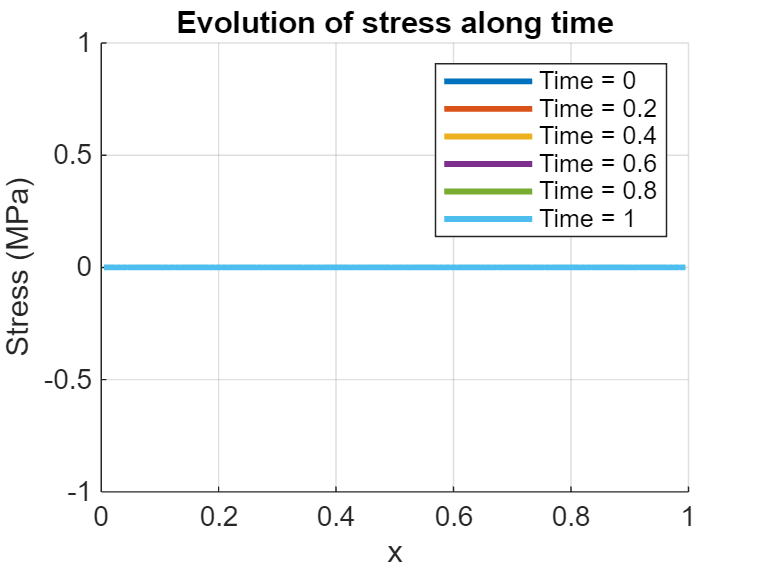

% Evolution of stresses along time
% --------------------------------------------
figure
hold on
xlabel('x')
ylabel('Stress (MPa)')
title('Evolution of stress along time')
COOR_gauss = (COOR(CN(:,2))+  COOR(CN(:,1)))/2 ;
nsteps_plot = length(stepsPOST) ;
hplot = zeros(nsteps_plot,1) ;
LegendPlot = cell(nsteps_plot,1) ;
for i = 1:nsteps_plot
    hplot(i) =  plot(COOR_gauss,STRESS_GLO(:,stepsPOST(i),3),'LineWidth',2) ;
    %LegendPlot{i} = ['Time = ',num2str(TIMES(stepsPOST(i))),'; NELEM =',num2str(NELEM),'; NSTEP = ',num2str(nsteps)] ;
    LegendPlot{i} = ['Time = ',num2str(TIMES(stepsPOST(i)))] ;
end
grid on
legend(hplot,LegendPlot)

legend('off')
legend

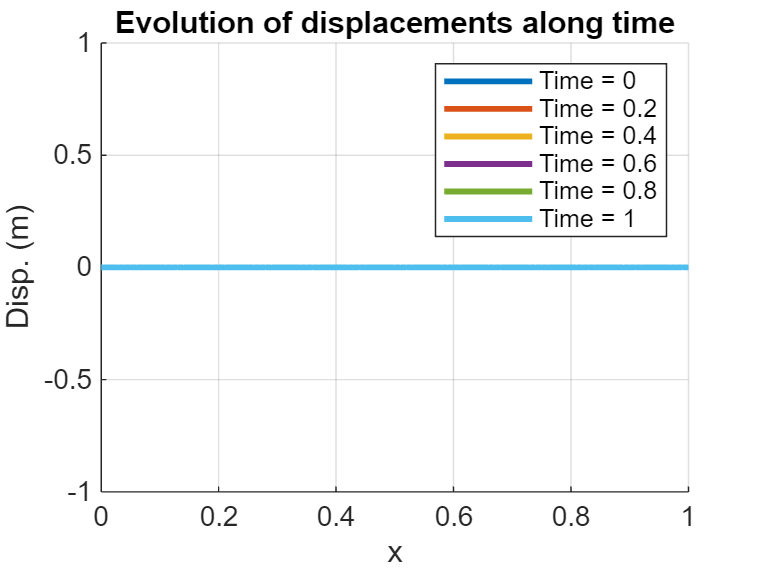


% Evolution of displacements along time
% --------------------------------------------
figure
hold on
xlabel('x')
ylabel('Disp. (m)')
title('Evolution of displacements along time')
nsteps_plot = length(stepsPOST) ;
hplot = zeros(nsteps_plot,1) ;
LegendPlot = cell(nsteps_plot,1) ;
for i = 1:nsteps_plot
    hplot(i) =  plot(COOR,d_GLO(:,stepsPOST(i),3),'LineWidth',2) ;
   %LegendPlot{i} = ['Time = ',num2str(TIMES(stepsPOST(i))),'; NELEM =',num2str(NELEM),'; NSTEP = ',num2str(nsteps)] ;
    LegendPlot{i} = ['Time = ',num2str(TIMES(stepsPOST(i)))] ;

end
grid on
legend(hplot,LegendPlot)

legend('off')
legend

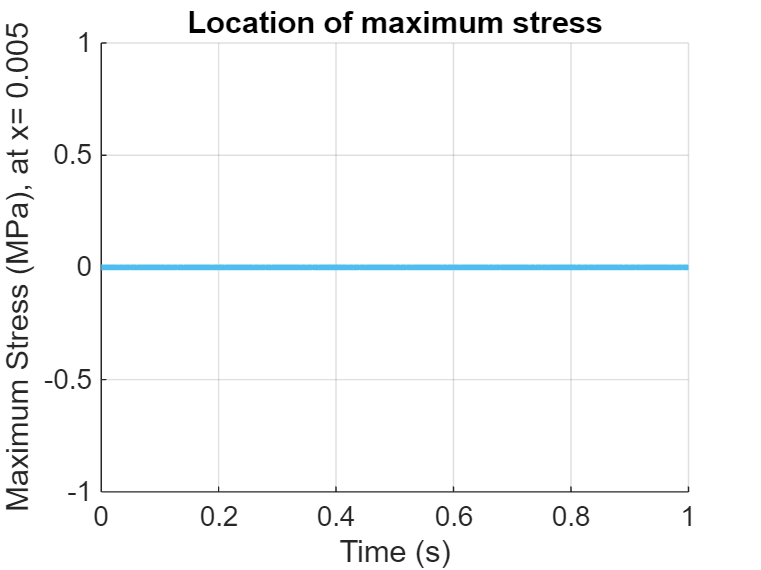




% Location of maximum stress

[stressEND,indELEM ]= max(STRESS_GLO(:,end,1)) ;
COOR_max_stress= COOR_gauss(indELEM) ;

figure
hold on
title('Location of maximum stress')
xlabel('Time (s)')
ylabel(['Maximum Stress (MPa), at x= ',num2str(COOR_max_stress)]) ;
for i = 1:nsteps_plot
    h =   plot(TIMES,STRESS_GLO(indELEM,:,1),'LineWidth',2) ;
end
grid on

%legend(h,['NELEM =',num2str(NELEM),'; NSTEP = ',num2str(nsteps)])

%legend('off')
%legend

